# LAB2 - Problem 1 (Fixed boundaries + stacked click-to-check)

Sentence: "Oak is strong and also gives shade." Requirements implemented step by step: 1) ARPAbet transcription 2) Segmentation + labeling of s5.wav 3) Zero out all vowel regions 4) Zero out all consonant regions 5) Listen and judge intelligibility

clear; clc; close all;

## Setup

labDir = '/Users/hwy/Desktop/个人/26春/语音信号处理/lab2';
inWav = fullfile(labDir, 's5.wav');

if ~isfile(inWav)
    error('Input file not found: %s', inWav);
end

[x, fs] = audioread(inWav);
if size(x, 2) > 1
    x = mean(x, 2);
end
x = x(:);
N = numel(x);
t = (0:N-1).' / fs;
audioDur = N / fs;

## Step 1: ARPAbet transcription

Oak(OW K) is(IH Z) strong(S T R AO NG) and(AE N D) also(AO L S OW) gives(G IH V Z) shade(SH EY D)

arpabetSentence = 'OW K | IH Z | S T R AO NG | AE N D | AO L S OW | G IH V Z | SH EY D';
fprintf('\nStep 1 - ARPAbet transcription:\n%s\n\n', arpabetSentence);


Step 1 - ARPAbet transcription:
OW K | IH Z | S T R AO NG | AE N D | AO L S OW | G IH V Z | SH EY D



## Step 2: Fixed segmentation + labels

labels = {'SIL', 'OW', 'K', 'IH', 'Z', 'S', 'T', 'R', 'AO', 'NG', ...
          'AE', 'N', 'D', 'AO', 'L', 'S', 'OW', 'G', 'IH', 'V', ...
          'Z', 'SH', 'EY', 'D', 'SIL'};

% Final fixed boundaries (seconds), 26 points for 25 segments.
boundarySec = [ ...
    0.000000, 0.159875, 0.279875, 0.344875, 0.579875, 0.724875, ...
    0.769875, 0.784875, 0.804875, 0.864875, 1.194875, 1.214875, ...
    1.274875, 1.319875, 1.369875, 1.499875, 1.589875, 1.684875, ...
    1.779875, 1.884875, 1.934875, 1.999875, 2.094875, 2.349875, ...
    2.429875, 3.000000 ...
];

if numel(boundarySec) ~= numel(labels) + 1
    error('Boundary count mismatch: expected %d, got %d', numel(labels)+1, numel(boundarySec));
end

boundarySec(end) = audioDur;
bounds = round(boundarySec * fs) + 1;
bounds(1) = 1;
bounds(end) = N + 1;

nSeg = numel(bounds) - 1;

vowelSet = {'AA','AE','AH','AO','AW','AY','EH','ER','EY','IH','IY', ...
    'OW','OY','UH','UW','AX','AXR','IX','UX'};

types = cell(nSeg, 1);
for k = 1:nSeg
    lab = regexprep(labels{k}, '\\d', '');
    if strcmp(lab, 'SIL') || strcmp(lab, 'SILENCE') || strcmp(lab, 'SP')
        types{k} = 'silence';
    elseif any(strcmp(lab, vowelSet))
        types{k} = 'vowel';
    else
        types{k} = 'consonant';
    end
end

words = {'-', 'Oak', 'Oak', 'is', 'is', 'strong', 'strong', 'strong', 'strong', 'strong', ...
         'and', 'and', 'and', 'also', 'also', 'also', 'also', 'gives', 'gives', 'gives', ...
         'gives', 'shade', 'shade', 'shade', '-'}.';

% Print and save boundary table
segStart = ((bounds(1:end-1)-1) / fs).';
segEnd = ((bounds(2:end)-2) / fs).';
segmentId = (1:nSeg).';
labelCol = labels(:);
typeCol = types(:);
wordCol = words(:);

if ~isequal(numel(segmentId), numel(segStart), numel(segEnd), ...
        numel(labelCol), numel(typeCol), numel(wordCol))
    error('Table column length mismatch in segmentation output.');
end

segmentTable = table(segmentId, segStart, segEnd, labelCol, typeCol, wordCol, ...
    'VariableNames', {'Segment', 'Start_s', 'End_s', 'Label', 'Type', 'Word'});

fprintf('Step 2 - Boundary table:\n');

Step 2 - Boundary table:


disp(segmentTable);

    Segment    Start_s     End_s      Label         Type            Word   
    _______    _______    _______    _______    _____________    __________
       1             0    0.15975    {'SIL'}    {'silence'  }    {'-'     }
       2       0.15987    0.27975    {'OW' }    {'vowel'    }    {'Oak'   }
       3       0.27987    0.34475    {'K'  }    {'consonant'}    {'Oak'   }
       4       0.34487    0.57975    {'IH' }    {'vowel'    }    {'is'    }
       5       0.57988    0.72475    {'Z'  }    {'consonant'}    {'is'    }
       6       0.72488    0.76975    {'S'  }    {'consonant'}    {'strong'}
       7       0.76987    0.78475    {'T'  }    {'consonant'}    {'strong'}
       8       0.78487    0.80475    {'R'  }    {'consonant'}    {'strong'}
       9       0.80488    0.86475    {'AO' }    {'vowel'    }    {'strong'}
      10       0.86487     1.1947    {'NG' }    {'consonant'}    {'strong'}
      11        1.1949     1.2147    {'AE' }    {'vowel'    }    {'and'   }
      12    


writetable(segmentTable, 'problem1_segments.csv');
fprintf('Saved segmentation file: %s\n\n', fullfile(pwd, 'problem1_segments.csv'));

Saved segmentation file: /Users/hwy/Desktop/个人/26春/语音信号处理/lab2/problem1_segments.csv



## Stacked waveform figure (color by type)

chunkLen = 4000;                 % samples per row
ampScale = 900;                  % visual amplitude scaling
nRows = ceil(N / chunkLen);

fig = figure('Name', 'Problem 1 - Fixed Segmentation (stacked click-to-play)', 'Color', 'w');
ax = axes(fig);
plotStackedWaveform(ax, x, chunkLen, ampScale, 'k', 1.5);
hold(ax, 'on');
grid(ax, 'on');

for k = 2:numel(bounds)-1
    b = bounds(k);
    segType = types{k};
    c = typeColor(segType);
    [xLocal, ~, yMin, yMax] = sampleToStackCoord(b, chunkLen, ampScale);
    line(ax, [xLocal xLocal], [yMin yMax], 'Color', c, 'LineWidth', 1.2);
end

for k = 1:nSeg
    mid = round((bounds(k) + bounds(k+1)-1) / 2);
    c = typeColor(types{k});
    [xLocal, yBase] = sampleToStackCoord(mid, chunkLen, ampScale);
    yText = yBase - 0.62 * ampScale;
    text(ax, xLocal, yText, labels{k}, 'Color', c, ...
        'HorizontalAlignment', 'center', 'FontSize', 11, 'FontWeight', 'bold');
end

xlim(ax, [0 chunkLen]);
yMin = -0.95 * ampScale;
yMax = nRows * chunkLen + 0.95 * ampScale;
ylim(ax, [yMin yMax]);
set(ax, 'YDir', 'reverse');

yt = (0:nRows-1) * chunkLen + 1;
set(ax, 'YTick', yt, 'YTickLabel', string(yt));

xlabel(ax, 'Samples within each row');
ylabel(ax, 'Global sample index (row baseline)');
title(ax, 'Fixed segmentation (Blue=vowel, Red=consonant, Gray=silence)');

segData = struct('x', x, 'fs', fs, 't', t, 'bounds', bounds, 'labels', {labels}, ...
    'ax', ax, 'chunkLen', chunkLen, 'nRows', nRows);
setappdata(fig, 'segData', segData);
set(fig, 'WindowButtonDownFcn', @(src,evt)playClickedSegmentStacked(src));
uicontrol(fig, 'Style', 'pushbutton', 'String', 'Continue', 'Units', 'normalized', ...
    'Position', [0.86 0.93 0.12 0.055], 'FontSize', 10, 'FontWeight', 'bold', ...
    'Callback', @(~,~)uiresume(fig));

fprintf('Stacked figure ready. Click any region to play that segment.\n');

Stacked figure ready. Click any region to play that segment.


fprintf('Playing full original sentence once...\n');

Playing full original sentence once...


soundsc(x, fs);
fprintf('Preview mode: click segments to listen. Click "Continue" when finished.\n');

Preview mode: click segments to listen. Click "Continue" when finished.


uiwait(fig);
if isgraphics(fig)
    close(fig);
end

## Step 3/4: Zero out vowels vs consonants

vowelMask = false(N, 1);
consMask = false(N, 1);

for k = 1:nSeg
    idx = bounds(k):(bounds(k+1)-1);
    if strcmp(types{k}, 'vowel')
        vowelMask(idx) = true;
    elseif strcmp(types{k}, 'consonant')
        consMask(idx) = true;
    end
end

xNoVowels = x;
xNoVowels(vowelMask) = 0;

xNoConsonants = x;
xNoConsonants(consMask) = 0;

outNoVowels = fullfile(pwd, 'problem1_no_vowels.wav');
outNoConsonants = fullfile(pwd, 'problem1_no_consonants.wav');
audiowrite(outNoVowels, xNoVowels, fs);
audiowrite(outNoConsonants, xNoConsonants, fs);

## Plot: original vs modified waveforms

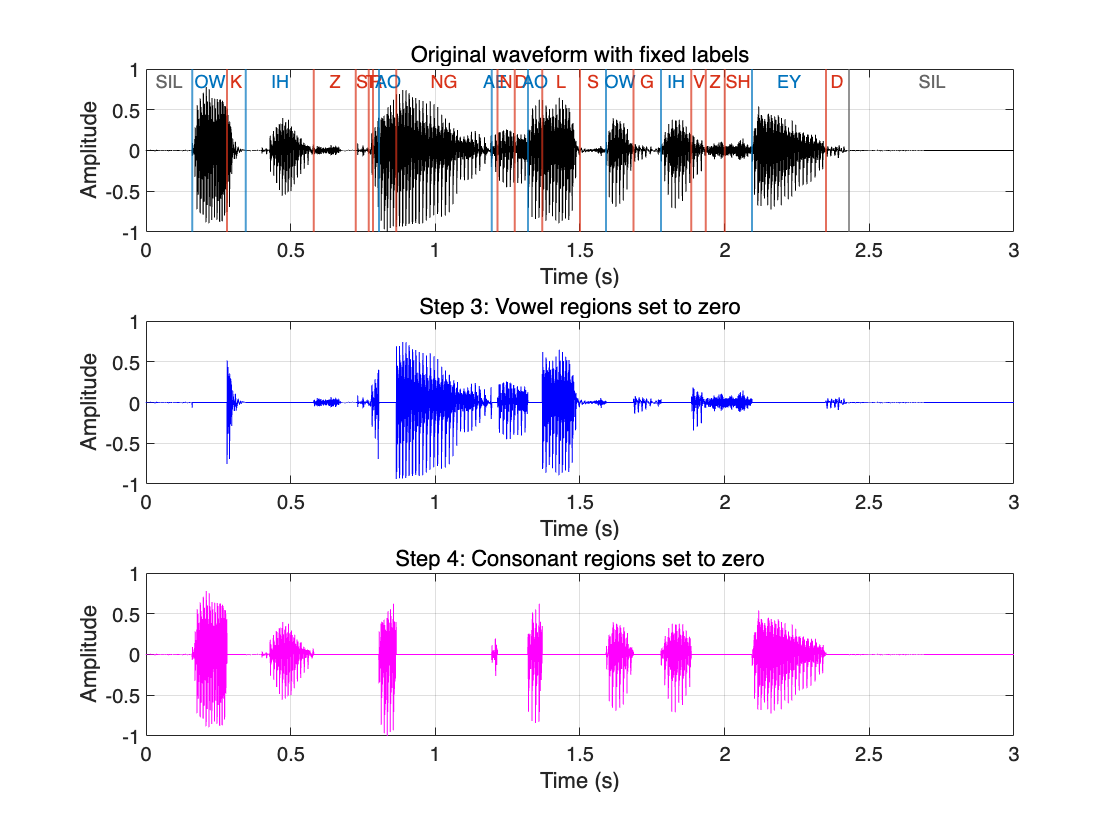

figure('Name', 'Problem 1 Results', 'Color', 'w');

subplot(3,1,1);
plot(t, x, 'k'); hold on; grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title('Original waveform with fixed labels');
for k = 2:numel(bounds)-1
    xline((bounds(k)-1)/fs, '-', 'Color', typeColor(types{k}), 'LineWidth', 1.0);
end
yl = ylim;
for k = 1:nSeg
    tm = ((bounds(k) + bounds(k+1))/2 - 1) / fs;
    text(tm, yl(2)*0.85, labels{k}, 'Color', typeColor(types{k}), ...
        'HorizontalAlignment', 'center', 'FontSize', 9);
end

subplot(3,1,2);
plot(t, xNoVowels, 'b'); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title('Step 3: Vowel regions set to zero');

subplot(3,1,3);
plot(t, xNoConsonants, 'm'); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title('Step 4: Consonant regions set to zero');

## Step 5: Listen and judge intelligibility

fprintf('\nStep 5 - Intelligibility check:\n');


Step 5 - Intelligibility check:


fprintf('Playing: original -> no vowels -> no consonants\n');

Playing: original -> no vowels -> no consonants


soundsc(x, fs); pause(numel(x)/fs + 0.5);
soundsc(xNoVowels, fs); pause(numel(xNoVowels)/fs + 0.5);
soundsc(xNoConsonants, fs);

fprintf('Saved audio:\n- %s\n- %s\n', outNoVowels, outNoConsonants);

Saved audio:
- /Users/hwy/Desktop/个人/26春/语音信号处理/lab2/problem1_no_vowels.wav
- /Users/hwy/Desktop/个人/26春/语音信号处理/lab2/problem1_no_consonants.wav


fprintf('Manually decide which one is more intelligible.\n');

Manually decide which one is more intelligible.


## Local functions

function c = typeColor(typeName)
    switch lower(typeName)
        case 'vowel'
            c = [0.00, 0.45, 0.74];     % blue
        case 'consonant'
            c = [0.85, 0.20, 0.10];     % red/orange
        otherwise
            c = [0.40, 0.40, 0.40];     % gray for silence
    end
end

function plotStackedWaveform(ax, x, chunkLen, ampScale, colorSpec, lw)
    N = numel(x);
    nRows = ceil(N / chunkLen);

    for r = 1:nRows
        st = (r-1) * chunkLen + 1;
        en = min(r * chunkLen, N);
        xLocal = (0:(en-st)).';
        yBase = (r-1) * chunkLen + 1;
        yPlot = yBase + x(st:en) * ampScale;
        plot(ax, xLocal, yPlot, 'Color', colorSpec, 'LineWidth', lw);
        hold(ax, 'on');
    end
end

function [xLocal, yBase, yMin, yMax] = sampleToStackCoord(sampleIdx, chunkLen, ampScale)
    row = floor((sampleIdx - 1) / chunkLen) + 1;
    yBase = (row - 1) * chunkLen + 1;
    rowStart = (row - 1) * chunkLen + 1;
    xLocal = sampleIdx - rowStart;
    yMin = yBase - 0.42 * ampScale;
    yMax = yBase + 0.42 * ampScale;
end

function playClickedSegmentStacked(fig)
    data = getappdata(fig, 'segData');
    if isempty(data) || ~isfield(data, 'ax') || ~ishandle(data.ax)
        return;
    end

    cp = get(data.ax, 'CurrentPoint');
    xClick = cp(1,1);
    yClick = cp(1,2);

    if xClick < 0 || xClick > data.chunkLen
        return;
    end

    row = floor((yClick - 1) / data.chunkLen) + 1;
    if row < 1 || row > data.nRows
        return;
    end

    s = (row - 1) * data.chunkLen + round(xClick) + 1;
    s = min(max(s, 1), numel(data.x));

    k = find(data.bounds(1:end-1) <= s & s < data.bounds(2:end), 1, 'first');
    if isempty(k)
        return;
    end

    pad = round(0.01 * data.fs);
    st = max(1, data.bounds(k) - pad);
    en = min(numel(data.x), data.bounds(k+1)-1 + pad);
    idx = st:en;

    soundsc(data.x(idx), data.fs);
    fprintf('Clicked segment %d: %s (%.3f s -> %.3f s)\n', k, data.labels{k}, ...
        (data.bounds(k)-1)/data.fs, (data.bounds(k+1)-2)/data.fs);

    title(data.ax, sprintf('Clicked segment %d = %s (%.3f-%.3f s)', ...
        k, data.labels{k}, (data.bounds(k)-1)/data.fs, (data.bounds(k+1)-2)/data.fs));
end